clear all
close all
clc

m = 0.2;
w0 = 2*pi*1e3;

syms t p

fs = 455;

ve = cos(2*pi*fs.*t);

VE = laplace(ve,t,p);

H = 1./(1+2*m*(p/w0)+(p/w0)^2);
vs = ilaplace(H*VE,p,t);

t = linspace(0,5e-3,1000);

ve = subs(ve);
vs = subs(vs);


A = max(ve)-max(vs)

$$A = \frac{1268760000\,{\mathrm{e}}^{-\frac{596\,\pi }{333}}\,\left(\cos\left(\frac{1192\,\pi \,\sqrt{6}}{333}\right)+\frac{48281\,\sqrt{6}\,\sin\left(\frac{1192\,\pi \,\sqrt{6}}{333}\right)}{380628}\right)}{1059093361}-\frac{291200000\,\sin\left(\frac{239\,\pi }{3330}\right)}{1059093361}-\frac{1268760000\,\cos\left(\frac{239\,\pi }{3330}\right)}{1059093361}+1$$

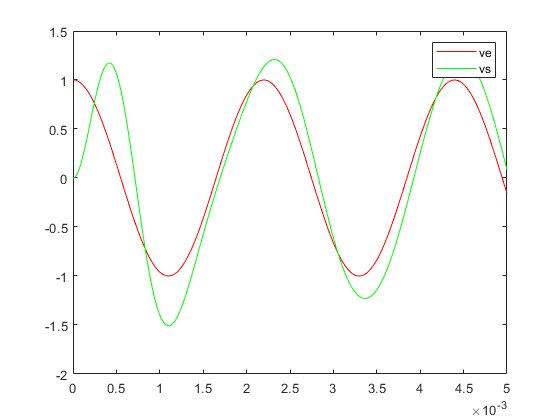


plot(t, ve,'r')
hold on
plot(t,vs,'g')
legend("ve","vs");

origine_ve = ve(0);

Array indices must be positive integers or logical values.

Error in sym/subsref (line 898)
            R_tilde = builtin('subsref',L_tilde,Idx);


[A,t_max] = max(vs);



% H = subs(H);
% 
% G = 20.*log10(abs(H))
% 
% f = logspace(0,6,1000);
% 
% subplot(2,1,1)
% semilogx(f,G);
% title("Diagramme de Bode")
% 
% subplot(2,1,2)
% semilogx(f,angle(H));
% title("Argument")
